Importando a matriz de relação completa

clear; clc;
res = readmatrix('C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\data-analisys\tables\res.csv');

Coloca os elementos em ordem de acordo com a maior soma das aparições de tais palavras nos emails

qtdLinCol = size(res);
res = res(:,1:qtdLinCol(2)-2);
order = rand(0, qtdLinCol(2)-2);
for i = 1:1:qtdLinCol(2)-2
    order(i) = sum(res(2:qtdLinCol(1),i));
end
order = order';
[val, pos] = sort(order, 'descend');

Filtra esses resultados em somente 300 palavras relevantes

varQtd = 300;
data = res(:,1:varQtd);
data(:,varQtd+1) = res(:,1);
for i = 1:1:varQtd
    data(:,i) = res(:,pos(i,1));
end
writematrix(data, 'C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\data-analisys\tables\data.csv');

Importa a matriz já gerada

data = readmatrix('C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\data-analisys\tables\data.csv');
qtdLnCl = size(data);

Remove Valores duplicados da matriz

colN = data(1,:);
data = unique(data(2:qtdLnCl(1),:),'rows');
data(1,:) = colN;
qtdLnCl2 = size(data);
fprintf('Foram %.0f linhas duplicadas', qtdLnCl(1) - qtdLnCl2(1));

Foram 509 linhas duplicadas

Encontra as melhores variaveis para a classificação através do metódo estatístico fscchi2 e recria uma nova base de dados com um valor menor de variaveis

[idx, scores] = fscchi2(data(2:qtdLnCl2(1),1:varQtd), data(2:qtdLnCl2(1),varQtd+1));
qtdVar = varQtd/5

qtdVar = 60

dataF = data(:,2);
dataF(:,qtdVar+1) = data(:,varQtd+1);
for j = 1:1:qtdVar
    dataF(:,j) = data(:,idx(j));
end
dataF = dataF(2:3030,2:qtdVar+1);
writematrix(dataF, 'C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\data-analisys\tables\final.csv');


for i = 1:1:qtdVar-1                                                 %Normaliza as entradas Min-Max%
    x2(:,i) = (X(:,i)-min(X(:,i)))/(max(X(:,i)) - min(X(:,i)));
end

analise da base de dados quantidade de palavras utilizadas

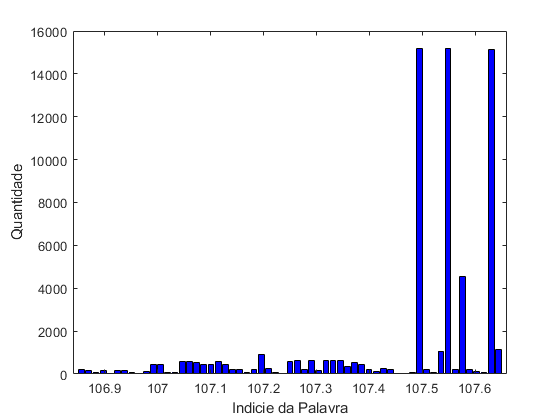

sizeX = size(x2);
sumX = x2(:,1);
for i = 1:1:sizeX(2)
    sumX = sum(x2(:,i));
end
bar(sumX, dataF(1,2:60),'b');
ylabel('Quantidade');
xlabel('Indicie da Palavra');

Analise quantidade de palavras por email falso e verdadeiro

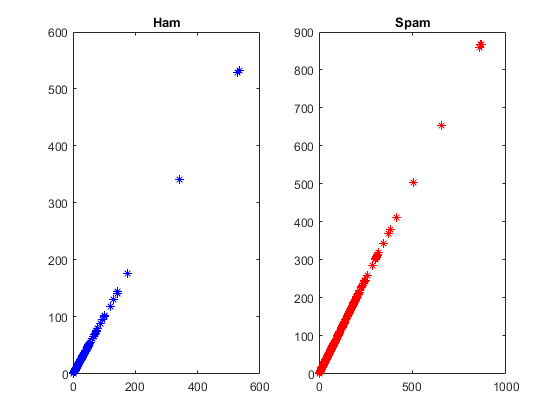

sizeX = size(X);
spamQtd =  1;
spam = x2(:,1);
hamQtd =  1;
ham = x2(:,1);
for i = 1:1:sizeX(1)
    if Y(i) == 0
        spam(spamQtd) = sum(X(i,:));
        spamQtd = spamQtd+1;
    else
        ham(hamQtd) = sum(X(i,:));
        hamQtd = hamQtd+1;
    end
end
figure(5);
subplot(1,2,1);
plot(ham,ham, '*b');
title("Ham");
subplot(1,2,2);
plot(spam,spam, '*r');
title("Spam");

Gerando boxplot

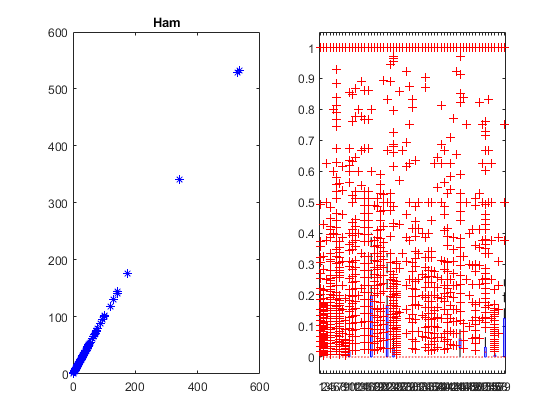

boxplot(x2);